# Remove Noise with Nonlinear Filters

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

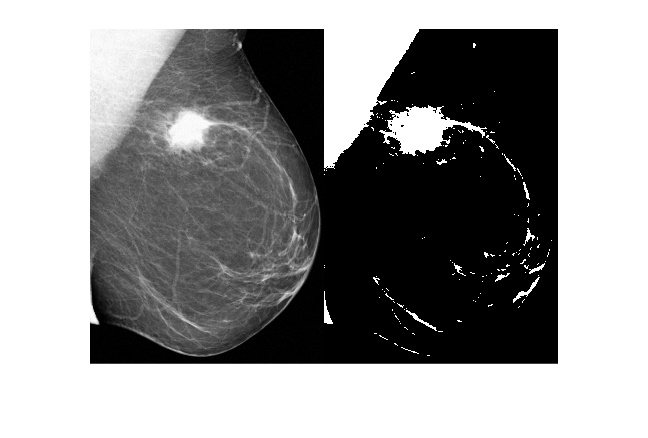

tumor = readmatrix("./images/tumorReducedSize.csv", OutputType="uint8");
tumorBW = imbinarize(tumor);
imshowpair(tumor, tumorBW, "montage")

## Task 1

You can use `medfilt2` to replace each pixel with the median of the ones around it.

`imFiltMed` `=` `medfilt2``(``im``,``filterSize``)``;`

The filter size is a 2-element vector that specifies the filtering neighborhood of pixels.

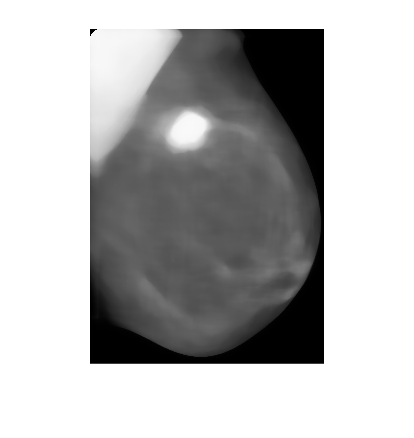

filterSize = [15 15];
tumorMed = medfilt2(tumor, filterSize); 
imshow(tumorMed)

## Task 2

The median filtered image has lost a lot of detail inside the tissue, but the edges are still crisp.

The goal of this preprocessing is to create a segmentation of the tumor. One way to segment a grayscale image is with the `imbinarize` function.

`BW` `=` `imbinarize``(``gs``)``;`

The output `BW` is a binary image where foreground pixels have value `1` and background pixels have value `0`.

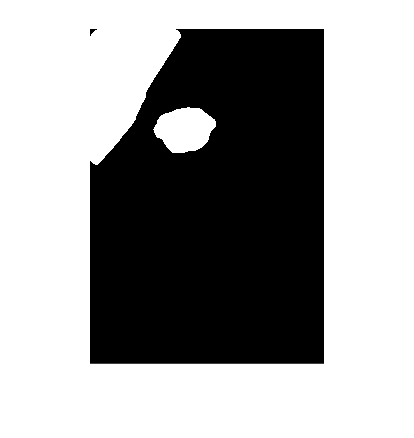

tumorMedBW = imbinarize(tumorMed);
imshow(tumorMedBW)

## Task 3

Another edge-preserving, nonlinear filter is the Wiener filter, which is adaptive. You can use the `wiener2` function with the same syntax as `medfilt2`.

`imFiltW` `=` `wiener2``(``im``,``filterSize``)``;`

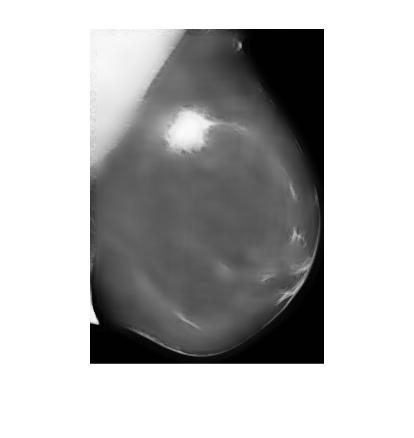

filterSize = [15 15];
tumorW = wiener2(tumor, filterSize);
imshow(tumorW)

## Task 4

Let's see the effect on the segmentation.

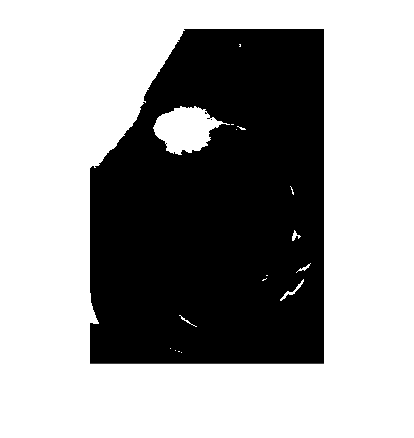

tumorWBW = imbinarize(tumorW);
imshow(tumorWBW)